% Pacheck, Nicholas 
% 2-D Beamforming Antenna Array Patterns

clc, clear, clearvars

% Define signal parameters
freq = 10e6;
omega = 2*pi*freq;
speed0light = 3e8;
wavelen = speed0light/freq;
k = (2*pi)/wavelen;

%Tune parameters
f0 = 10e6;
wavelen0 = speed0light/f0;
k0 = (2*pi)/wavelen0;

% Define array parameters
spacing = wavelen/2;
xnAntennas = 10;
ynAntennas = 10;


% Define cartesisan coordintate basis for coordinates
x_basis = linspace(0, xnAntennas*spacing, xnAntennas);
y_basis = linspace(0, ynAntennas*spacing, ynAntennas)

y_basis =          0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000


% Convert basis vectors into a spanning gridspace
[x_span, y_span ] = meshgrid(x_basis, y_basis)

x_span =          0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  133.3333  150.0000
         0   16.6667   33.3333   50.0000   66.6667   83.3333  100.0000  116.6667  

y_span =          0         0         0         0         0         0         0         0         0         0
   16.6667   16.6667   16.6667   16.6667   16.6667   16.6667   16.6667   16.6667   16.6667   16.6667
   33.3333   33.3333   33.3333   33.3333   33.3333   33.3333   33.3333   33.3333   33.3333   33.3333
   50.0000   50.0000   50.0000   50.0000   50.0000   50.0000   50.0000   50.0000   50.0000   50.0000
   66.6667   66.6667   66.6667   66.6667   66.6667   66.6667   66.6667   66.6667   66.6667   66.6667
   83.3333   83.3333   83.3333   83.3333   83.3333   83.3333   83.3333   83.3333   83.3333   83.3333
  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
  116.6667  116.6667  116.6667  116.6667  116.6667  116.6667  116.6667  116.6667  116.6667  116.6667
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333
  150.0000  150.0000  150.0000  150.0000  150.0000  150.0000  150.0000  150.0000  


% Define sinspace converting anon function
ssU = @(azim_param, elev_param) sind(azim_param).*cosd(elev_param);
ssV = @(azim_param, elev_param) sind(azim_param).*sind(elev_param);
sineSpace = @( azim_param, elev_param ) [ssU(azim_param, elev_param); ssV(azim_param, elev_param)];

% Define azimuthal and elevation spans
azim_basis = linspace(-90, 90, 180);
elev_basis = linspace(0, 180, 180)

elev_basis =          0    1.0056    2.0112    3.0168    4.0223    5.0279    6.0335    7.0391    8.0447    9.0503   10.0559   11.0615   12.0670   13.0726   14.0782   15.0838   16.0894   17.0950   18.1006   19.1061   20.1117   21.1173   22.1229   23.1285   24.1341   25.1397   26.1453   27.1508   28.1564   29.1620   30.1676   31.1732   32.1788   33.1844   34.1899   35.1955   36.2011   37.2067   38.2123   39.2179   40.2235   41.2291   42.2346   43.2402   44.2458   45.2514   46.2570   47.2626   48.2682   49.2737




% Define a sinespace grid
ssUspan = ssU(azim_basis, elev_basis)

ssUspan =    -1.0000   -0.9997   -0.9988   -0.9972   -0.9951   -0.9923   -0.9890   -0.9850   -0.9804   -0.9753   -0.9695   -0.9632   -0.9563   -0.9488   -0.9408   -0.9323   -0.9232   -0.9136   -0.9035   -0.8929   -0.8818   -0.8702   -0.8582   -0.8457   -0.8328   -0.8195   -0.8058   -0.7918   -0.7773   -0.7626   -0.7475   -0.7321   -0.7164   -0.7004   -0.6842   -0.6678   -0.6512   -0.6343   -0.6174   -0.6002   -0.5830   -0.5656   -0.5482   -0.5307   -0.5132   -0.4956   -0.4781   -0.4606   -0.4431   -0.4257


ssVspan = ssV(azim_basis, elev_basis)

ssVspan =          0   -0.0175   -0.0351   -0.0526   -0.0700   -0.0873   -0.1045   -0.1216   -0.1386   -0.1553   -0.1719   -0.1883   -0.2044   -0.2203   -0.2359   -0.2513   -0.2663   -0.2810   -0.2953   -0.3093   -0.3229   -0.3361   -0.3489   -0.3612   -0.3731   -0.3846   -0.3956   -0.4061   -0.4160   -0.4255   -0.4345   -0.4429   -0.4508   -0.4581   -0.4648   -0.4710   -0.4766   -0.4816   -0.4860   -0.4899   -0.4931   -0.4957   -0.4977   -0.4991   -0.4998   -0.5000   -0.4995   -0.4984   -0.4967   -0.4944





% Compute doa in sinespace
azim_doa = 90;
elev_doa = 90;
ssUdoa = ssU(azim_doa, elev_doa);
ssVdoa = ssV(azim_doa, elev_doa);

% Compute phase shifts that occur across both y and x axis
phasex_mat = k*ssUspan - k0*ssUdoa;
phasey_mat = k*ssVspan - k0*ssVdoa

phasey_mat =    -0.2094   -0.2131   -0.2168   -0.2204   -0.2241   -0.2277   -0.2313   -0.2349   -0.2385   -0.2420   -0.2454   -0.2489   -0.2523   -0.2556   -0.2589   -0.2621   -0.2652   -0.2683   -0.2713   -0.2742   -0.2771   -0.2798   -0.2825   -0.2851   -0.2876   -0.2900   -0.2923   -0.2945   -0.2966   -0.2986   -0.3004   -0.3022   -0.3038   -0.3054   -0.3068   -0.3081   -0.3093   -0.3103   -0.3112   -0.3120   -0.3127   -0.3133   -0.3137   -0.3140   -0.3141   -0.3142   -0.3141   -0.3138   -0.3135   -0.3130




AF = zeros(length(elev_basis))

AF =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

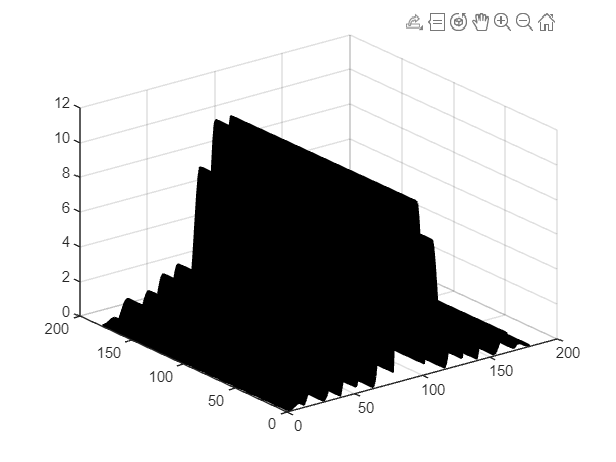

for ii = 1:xnAntennas
    for jj = 1:ynAntennas

        dx = ii*spacing;
        dy = jj*spacing;




        AF_i = exp(j*(dx.*phasex_mat + dy.*phasey_mat));


        AF = AF + AF_i;


    end 
end


surf(abs(AF))